# 相関係数の算出例

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all;

乱数を初期化する．かっこの中の数値を変えると異なる乱数が生成される．

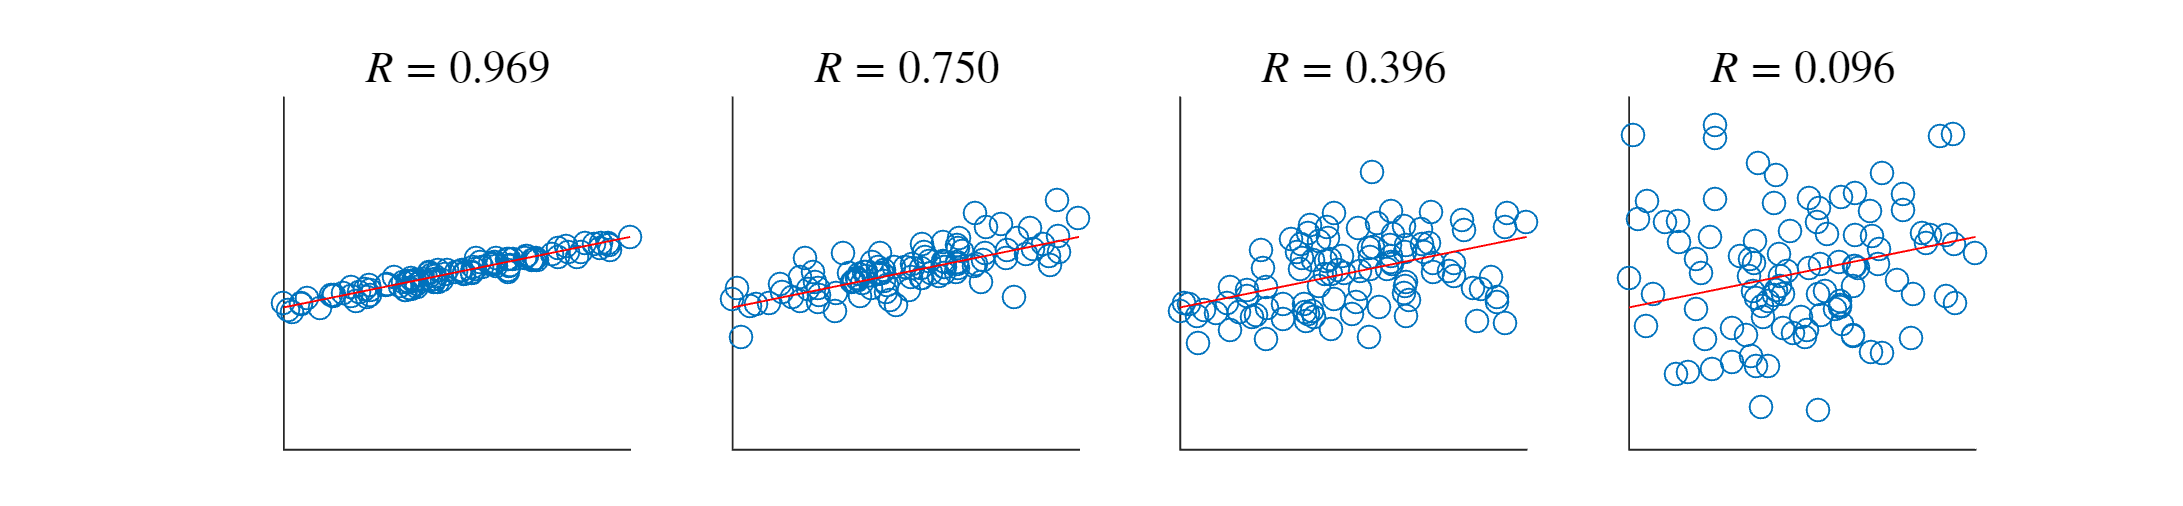

rng(1) %コメントを外すと書籍を同じ図が得られます

N=100;a=1;k=[0.25;1.0;2;3];
figure;
tiledlayout(1,size(k,1));
x=randn(N,1);
for n1=1:size(k,1)
    y=a*x+k(n1)*randn(N,1);
    nexttile;
    scatter(x,y);
    hold on;
    plot([min(x) max(x)],a*[min(x) max(x)],'r-');
    axis([min(x) max(x) 5*a*[min(x) max(x)]])
    xticks([]);yticks([]);
    title(['$R=' num2str(corr(x,y),'%1.3f') '$'],'Interpreter','latex','FontSize',12)
end
set(gcf,'Position',[680 719 1200 279]);
exportgraphics(gcf,'fig_corrExample.pdf');